# FISE_MTF

Visualization of the MTF.

Create a scene sweep frequency. The frequency increases from left to right.  The contrast is 1 across all the rows (y-dimension).

Pass the scene through the default optics. Notice that the contrast amplitude decreases as frequency increases. 

The ratio of the scene amplitude (1) to the optical image amplitude is the frequency dependent scale factor $s_f$. A good approximation to the MTF is the envelope of the sweep frequency response.  This is plotted as the red curve.

Finally, notice that we did nothing to account for the edges.  So the contrast at the left and right edge is not really any good.  How we account for edges in finite cases like this is an endless annoyance.  Welcome to the club!

## **Initialize ISETCam**

ieInit;

## Create the scene

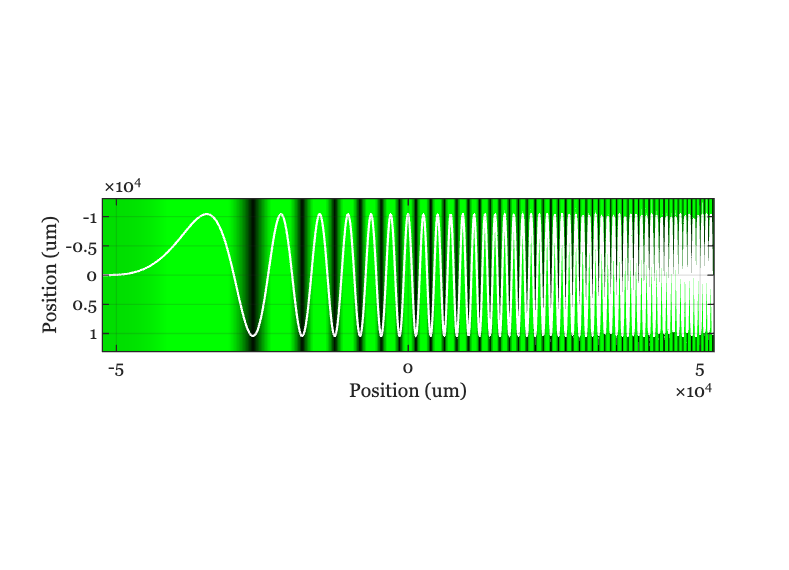

imSize = [256, 1024]; % row,col
maxF = 50;            % cycles/image
wave = 550;           % nm
yContrast = ones(1,imSize(1));  % Constant contrast across the rows

scene = sceneCreate('sweep frequency',imSize,maxF,wave,yContrast);

scene = sceneSet(scene,'fov',5);   % 50 cycles per 5 deg, so 10 cyc/deg

plotScene(scene,'luminance hline rgb',[1,round(imSize(1) / 2)]);

% exportgraphics(gca,'scenesweep.png');

## Create the Optical Image

oi = oiCreate("default");

oi = oiCompute(oi,scene,'crop',true);
fprintf('F/#: %.2f\nFocal length: %.2f\n', oiGet(oi,'fnumber'),oiGet(oi,'focal length','mm'));

F/#: 4.00
Focal length: 3.86


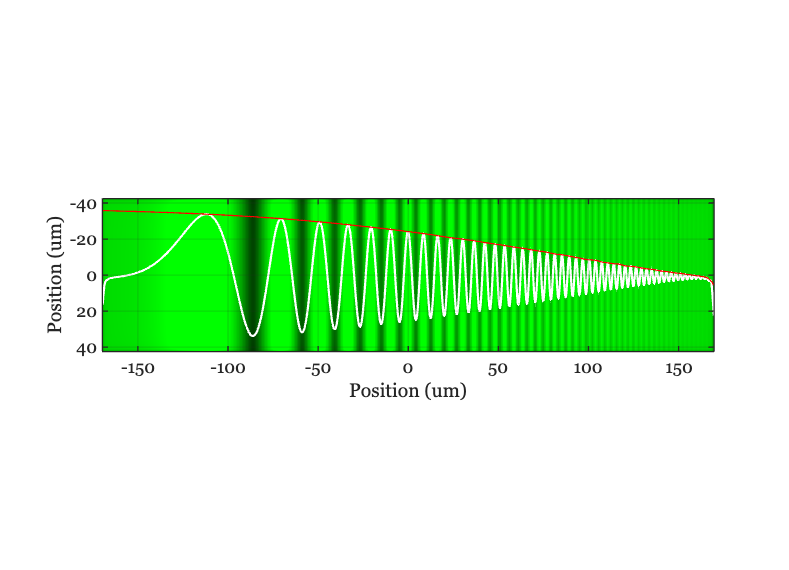

udata = plotOI(oi,'illuminance hline rgb',[1,round(imSize(1) / 2)]);
[upperEnvelope, lowerEnvelope] = envelope(-1*udata.data,5,'peak'); 
hold on;

plot(udata.pos,-1*upperEnvelope,'r-');

% exportgraphics(gca,'oisweep.png');